Loading the wideband SNR data. All values are in dB

load('WidebandSNRs.mat')

Checking total number of trajectories, # of TX beams, RX beams, BSs and Time samples (20 ms apart)

num_trajs = size(SNRs,1)

num_trajs = 100

num_BS = size(SNRs,2)

num_BS = 4

num_TXBeams = size(SNRs,3)

num_TXBeams = 64

num_RXBeams = size(SNRs,4)

num_RXBeams = 8

num_Timesamples = size(SNRs,5)

num_Timesamples = 3000

Let's see what the SNR on all TX/RX beams looks like from a particular base station at a particular time instance in a chosen trajectory

chosen_traj = randi([1 num_trajs])

chosen_traj = 4

chosen_time_instance = randi([1 num_Timesamples])

chosen_time_instance = 207

chosen_BS = randi([1 num_BS])

chosen_BS = 2

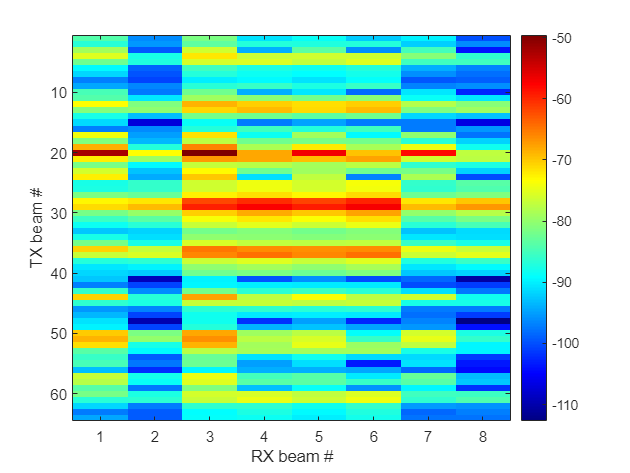


extracted_snr_grid = SNRs(chosen_traj,chosen_BS,:,:,chosen_time_instance);
extracted_snr_grid = reshape(extracted_snr_grid,num_TXBeams,num_RXBeams);
imagesc(extracted_snr_grid); colormap jet; colorbar; xlabel('RX beam #'); ylabel('TX beam #')

Now let us look at evolution of SNR with time from a particular TX RX beam pair

chosen_TXbeam = randi([1 num_TXBeams])

chosen_TXbeam = 34

chosen_RXbeam = randi([1 num_RXBeams])

chosen_RXbeam = 6

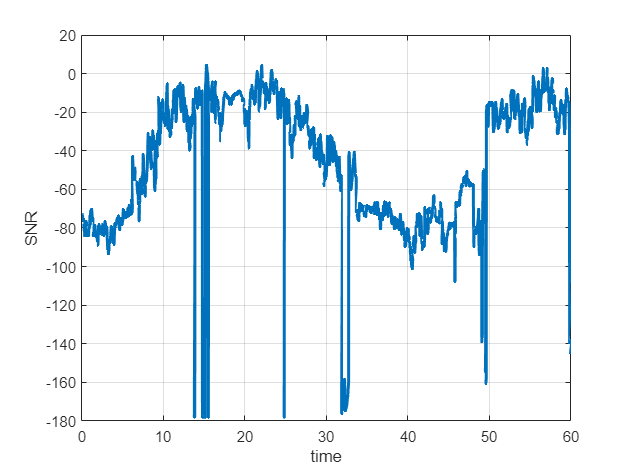


extracted_snr_with_time = SNRs(chosen_traj,chosen_BS,chosen_TXbeam,chosen_RXbeam,:);
extracted_snr_with_time = extracted_snr_with_time(:);

plot((1:num_Timesamples)*2e-2,extracted_snr_with_time,'LineWidth',2) %2e-2 because of 20 ms sampling interval
grid on
xlabel('time');ylabel('SNR')

Now let us see how this compares to the best possible SNR for the chosen trajectory and BS as well as the best SNR over all BS

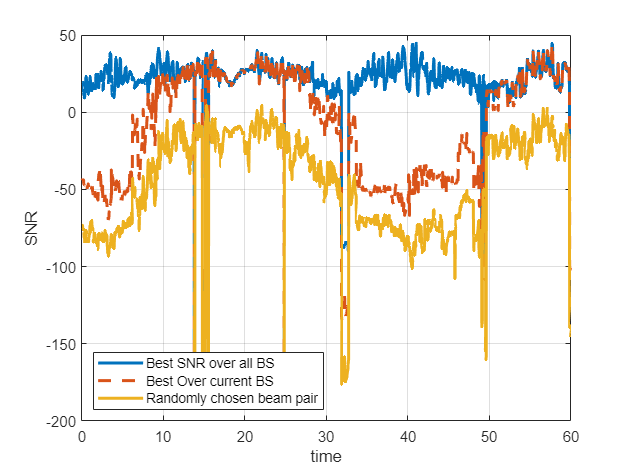

best_snr_current_bs = SNRs(chosen_traj,chosen_BS,:,:,:);
best_snr_current_bs = reshape(best_snr_current_bs,num_TXBeams,num_RXBeams,num_Timesamples);
best_snr_current_bs = max(best_snr_current_bs,[],[1,2]);
best_snr_current_bs = reshape(best_snr_current_bs,1,num_Timesamples);
best_snr_all_bs = SNRs(chosen_traj,:,:,:,:);
best_snr_all_bs = reshape(best_snr_all_bs,num_BS,num_TXBeams,num_RXBeams,num_Timesamples);
best_snr_all_bs = max(best_snr_all_bs,[],[1,2,3]);
best_snr_all_bs = reshape(best_snr_all_bs,1,num_Timesamples);

plot((1:num_Timesamples)*2e-2,best_snr_all_bs,'LineWidth',2)
hold on
plot((1:num_Timesamples)*2e-2,best_snr_current_bs,'--','LineWidth',2)
plot((1:num_Timesamples)*2e-2,extracted_snr_with_time,'LineWidth',2) %2e-2 because of 20 ms sampling interval
grid on
xlabel('time');ylabel('SNR')
legend('Best SNR over all BS','Best Over current BS','Randomly chosen beam pair','Location','southwest')